# Compares hydraulics and quality analysis functions.

## This example contains: 

- Load a network. 

- Set simulation duration. 

- Test hydraulics and quality analysis functions. 

- Step by step hydraulic analysis. 

- Step by step quality analysis. 

- Unload library. 

- Plot various analysis functions results.

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Load a network.

d = epanet('Net1.inp');tic;

EPANET version {20200} loaded (EMT version {v2.2.2 - Last Update: 07/08/2022}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


## Set simulation duration.

hours = 100;
d.setTimeSimulationDuration(hours*3600);

## Test hydraulics and quality analysis functions.

## Using ENepanet, create and read binary file.

Results = d.getComputedTimeSeries 

Results = struct with fields:
              Time: [101×1 double]
          Pressure: [101×11 double]
            Demand: [101×11 double]
              Head: [101×11 double]
       NodeQuality: [101×11 double]
              Flow: [101×13 double]
          Velocity: [101×13 double]
          HeadLoss: [101×13 double]
            Status: [101×13 double]
           Setting: [101×13 double]
      ReactionRate: [101×13 double]
    FrictionFactor: [101×13 double]
       LinkQuality: [101×13 double]
         StatusStr: {101×13 cell}


tocResults = toc;tic;

## Using the functions(ENopenH, ENinit, ENrunH, ENgetnodevalue/&ENgetlinkvalue, ENnextH, ENcloseH).

Hydraulics = d.getComputedHydraulicTimeSeries 

Hydraulics = struct with fields:
             Time: [109×1 double]
         Pressure: [109×11 double]
           Demand: [109×11 double]
    DemandDeficit: [109×11 double]
             Head: [109×11 double]
       TankVolume: [109×11 double]
             Flow: [109×13 double]
         Velocity: [109×13 double]
         HeadLoss: [109×13 double]
           Status: [109×13 double]
          Setting: [109×13 double]
           Energy: [109×13 double]
       Efficiency: [109×13 double]
            State: [109×1 double]
        StatusStr: {109×13 cell}
         StateStr: {109×1 cell}


tocHydraulics = toc;tic;

## ENopenQ, ENinitQ, ENrunQ, ENgetnodevalue/&ENgetlinkvalue, ENstepQ, ENcloseQ

Quality = d.getComputedQualityTimeSeries

Quality = struct with fields:
            Time: [1201×1 double]
     NodeQuality: [1201×11 double]
     LinkQuality: [1201×13 double]
    MassFlowRate: [1201×11 double]


tocQuality = toc;tic;

pipeindex=4;
nodeindex=6;

##  Step by step hydraulic analysis.

d.openHydraulicAnalysis;
d.initializeHydraulicAnalysis;
tstep=1;P=[];T_H=[];D=[];H=[];F=[];
while (tstep>0)
    t=d.runHydraulicAnalysis;
    P=[P; d.getNodePressure];
    D=[D; d.getNodeActualDemand];
    H=[H; d.getNodeHydaulicHead];
    F=[F; d.getLinkFlows];
    T_H=[T_H; t];
    tstep=d.nextHydraulicAnalysisStep;
end
d.closeHydraulicAnalysis

##  Step by step quality analysis.

d.openQualityAnalysis
d.initializeQualityAnalysis
tleft=1; P=[];T_Q=[];Q=[];  
sim_duration = d.getTimeSimulationDuration();
while (tleft>0 || t < sim_duration)
    t=d.runQualityAnalysis;
    Q=[Q; d.getNodeActualQuality];
    T_Q=[T_Q; t];
    tleft = d.stepQualityAnalysisTimeLeft;
end
d.closeQualityAnalysis;

##  Unload library.

d.unload

EPANET Class is unloaded


##  Plot various analysis functions results.

fprintf('\nSimulation duration: d hours\n', hours);


Simulation duration: d hours


disp(['Run Time of function d.getComputedTimeSeries: ', num2str(tocResults), '(sec)'])

Run Time of function d.getComputedTimeSeries: 1.3113(sec)


disp(['Run Time of function d.getComputedHydraulicTimeSeries: ', num2str(tocHydraulics), '(sec)'])

Run Time of function d.getComputedHydraulicTimeSeries: 0.68651(sec)


disp(['Run Time of function d.getComputedQualityTimeSeries: ', num2str(tocQuality), '(sec)'])

Run Time of function d.getComputedQualityTimeSeries: 1.4263(sec)


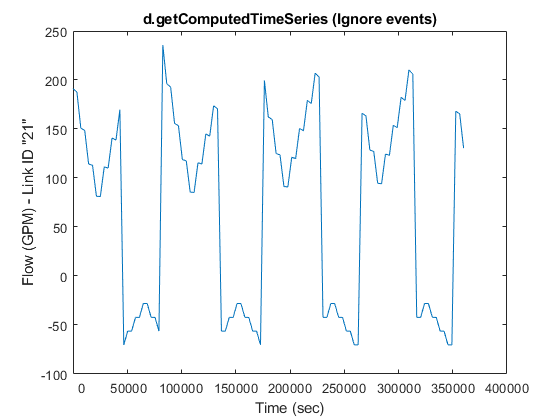


figure;
plot(Results.Time, Results.Flow(:,pipeindex));
title('d.getComputedTimeSeries (Ignore events)');
xlabel('Time (sec)'); ylabel(['Flow (',d.LinkFlowUnits,') - Link ID "',d.LinkNameID{pipeindex},'"'])
set(gca,'XTickLabel',num2str(get(gca,'XTick').'));

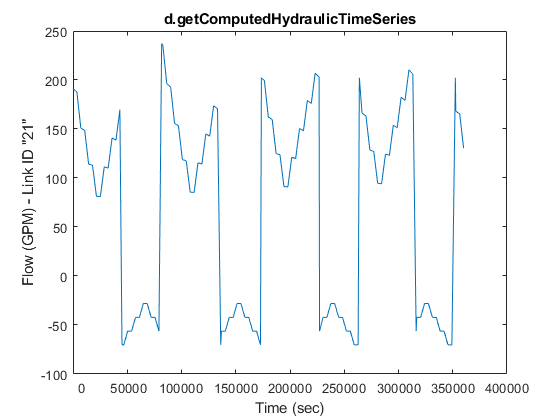


figure;
plot(Hydraulics.Time, Hydraulics.Flow(:,pipeindex));
title('d.getComputedHydraulicTimeSeries');
xlabel('Time (sec)'); ylabel(['Flow (',d.LinkFlowUnits,') - Link ID "',d.LinkNameID{pipeindex},'"'])
set(gca,'XTickLabel',num2str(get(gca,'XTick').'));

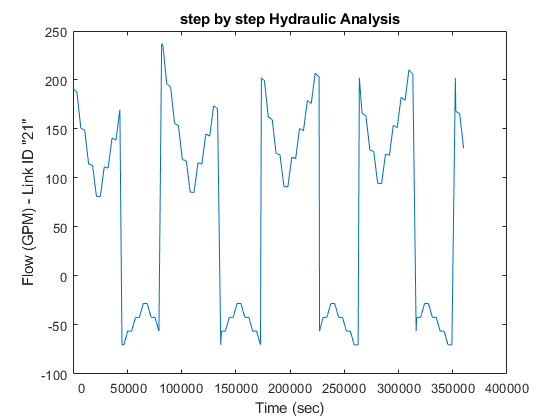


figure;
plot(T_H, F(:,pipeindex));
title('step by step Hydraulic Analysis');
xlabel('Time (sec)'); ylabel(['Flow (',d.LinkFlowUnits,') - Link ID "',d.LinkNameID{pipeindex},'"'])
set(gca,'XTickLabel',num2str(get(gca,'XTick').'));

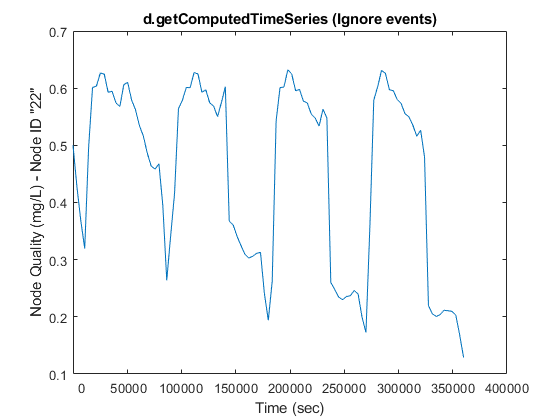


figure;
plot(Results.Time, Results.NodeQuality(:,nodeindex));
title('d.getComputedTimeSeries (Ignore events)');
xlabel('Time (sec)'); ylabel(['Node Quality (',d.QualityChemUnits,') - Node ID "',d.NodeNameID{nodeindex},'"'])
set(gca,'XTickLabel',num2str(get(gca,'XTick').'));

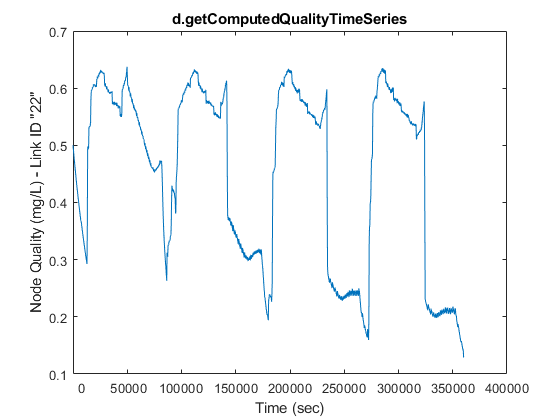


figure;
plot(Quality.Time, Quality.NodeQuality(:,nodeindex));
title('d.getComputedQualityTimeSeries');
xlabel('Time (sec)'); ylabel(['Node Quality (',d.QualityChemUnits,') - Link ID "',d.NodeNameID{nodeindex},'"'])
set(gca,'XTickLabel',num2str(get(gca,'XTick').'));

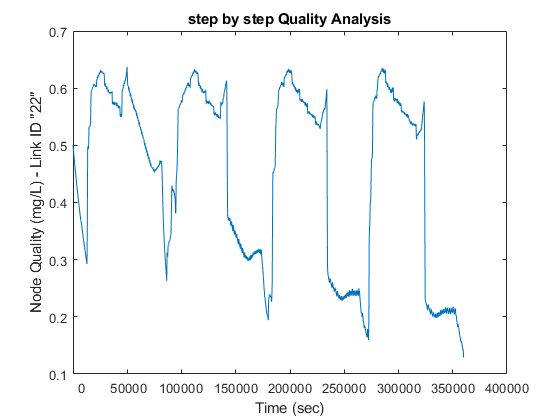


figure;
plot(T_Q, Q(:,nodeindex));
title('step by step Quality Analysis');
xlabel('Time (sec)'); ylabel(['Node Quality (',d.QualityChemUnits,') - Link ID "',d.NodeNameID{nodeindex},'"'])
set(gca,'XTickLabel',num2str(get(gca,'XTick').'));